# Sensitivity R0 comparison

## Model 10

syms beta_m beta_h theta_m theta_h mu_m gamma_h mu_h R_0
pars=[beta_m beta_h theta_m theta_h mu_m gamma_h mu_h];
R_0=(beta_m*beta_h*theta_h*theta_m/((theta_m+mu_m)*(gamma_h+mu_h)*(theta_h+mu_h)*(mu_m)))^(1/2)

$$R\_0 = \sqrt{\frac{\beta_{h}\,\beta_{m}\,\theta_{h}\,\theta_{m}}{\mu_{m}\,\left(\gamma_{h}+\mu_{h}\right)\,\left(\mu_{h}+\theta_{h}\right)\,\left(\mu_{m}+\theta_{m}\right)}}$$

load Results7.mat
[T,~]=gsua_dpmat(R_0,pars,1,'R_0');

Introduce ranges in the following order: 


$$ans = \left(\begin{array}{ccccccc} \beta_{m} & \beta_{h} & \theta_{m} & \theta_{h} & \mu_{m} & \gamma_{h} & \mu_{h} \end{array}\right)$$

common=intersect(T7.Properties.RowNames,T.Properties.RowNames);
T{common,'Range'}=T7{common,'Range'};
T{common,'Nominal'}=T7{common,'Nominal'};
T{'mu_h','Range'}=[4e-4,4e-4];
T{'mu_h','Nominal'}=4e-4

T = 7×2 table
                    Range          Nominal
               ________________    _______

    beta_m          0         4         2 
    beta_h          0         4         2 
    theta_m      0.58      0.88      0.73 
    theta_h       0.7      1.75     1.225 
    mu_m         0.16       0.2      0.18 
    gamma_h       0.5      1.75     1.125 
    mu_h       0.0004    0.0004    0.0004 


M=gsua_dmatrix(T,100000);
[T2,J,Y]=gsua_sa(M,T,'SensMethod','Xiao');

Progress: 12%
Estimated processing time (h:m:s): 0:0:0
Remaining time (h:m:s): 0:0:0
Elapsed time (h:m:s): 0:0:0
Estimated stop time (h:m:s): 17:23:38
Number of simulations: 450000
Progress: 23%
Estimated processing time (h:m:s): 0:0:0
Remaining time (h:m:s): 0:0:0
Elapsed time (h:m:s): 0:0:0
Estimated stop time (h:m:s): 17:23:38
Number of simulations: 450000
Progress: 34%
Estimated processing time (h:m:s): 0:0:1
Remaining time (h:m:s): 0:0:1
Elapsed time (h:m:s): 0:0:0
Estimated stop time (h:m:s): 17:23:39
Number of simulations: 450000
Progress: 45%
Estimated processing time (h:m:s): 0:0:1
Remaining time (h:m:s): 0:0:0
Elapsed time (h:m:s): 0:0:0
Estimated stop time (h:m:s): 17:23:39
Number of simulations: 450000
Progress: 56%
Estimated processing time (h:m:s): 0:0:1
Remaining time (h:m:s): 0:0:0
Elapsed time (h:m:s): 0:0:0
Estimated stop time (h:m:s): 17:23:38
Number of simulations: 450000
Progress: 67%
Estimated processing time (h:m:s): 0:0:0
Remaining time (h:m:s): 0:0:0
Elapsed ti

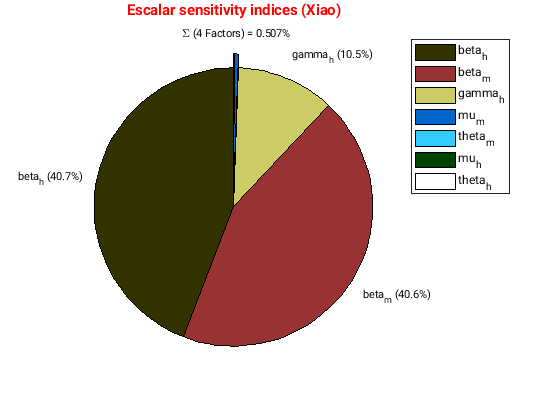

clf
gsua_plot('Pie',T2,T2.STi);
gsua_plot('Pie',T2,T2.Si);

Progress: 100%
Estimated processing time (h:m:s): 0:0:0
Remaining time (h:m:s): 0:0:0
Elapsed time (h:m:s): 0:0:0
Estimated stop time (h:m:s): 17:23:55
Number of simulations: 100000


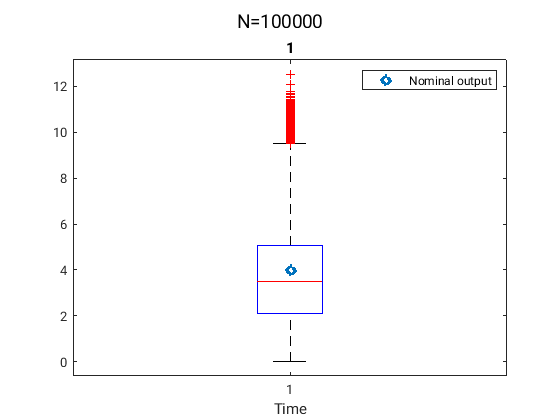

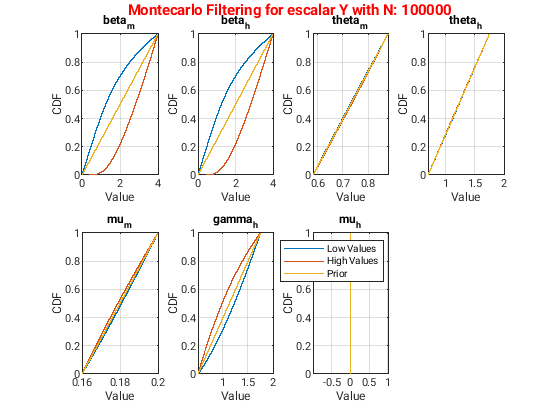

ans =     0.3160
    5.9964
    3.9914
    0.3302
    5.0025
    6.0764
    4.7998
    3.1439
    0.9019
    5.0634


gsua_ua(M,T,'xdata',0)

## Are there strong interactions?

sum(T2.STi_vec)

ans = 1.0865

sum(T2.Si_vec)

ans = 0.9187

## Fiability

sum(abs(T2.Si_vec))

ans = 0.9187

save('Results_r0.mat')